#### 2.a)Present the developed MATLAB function of Sim3A highlighting and justifying the introduced changes. Using Sim3A, estimate all performance parameters when lambda = 1500 pps, C = 10 Mbps, f = 1.000.000 Bytes, b = 10-5 and n = 10, 20, 30 and 40 VoIP flows, based on 20 runs of the simulator (with a stopping criterion of P = 100.000 on each run) and with 90% confidence intervals.

N = 20;
P = 100000;
alfa = 0.1; % 90% confidence interval
L = 1500;
C = 10;
F = 1000000;
B = 10^-5;
n = [10 20 30 40];


PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
MPDd_values = zeros(1,length(n));
TT_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));
MPDv_values = zeros(1,length(n));

PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
MPDd_terms = zeros(1,length(n));
TT_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));
MPDv_terms = zeros(1,length(n));

PLd = zeros(1,N);
APDd = zeros(1,N);
MPDd = zeros(1,N);
TT = zeros(1,N);
PLv = zeros(1,N);
APDv = zeros(1,N);
MPDv = zeros(1,N);

for i = 1:length(n)
    for x = 1:N
        [PLd(x),PLv(x),APDd(x),APDv(x),MPDd(x),MPDv(x),TT(x)] = Sim3A(L, C, F, P, n(i), B);
    end

    fprintf('For n = %d VoIP flows \n', n(i));
    
    % Calculate packet loss of data

    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media;
    PLd_terms(i) = term;
    fprintf('PacketLoss of data(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate packet loss of VoIP

    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media;
    PLv_terms(i) = term;
    fprintf('PacketLoss of VoIP(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of data

    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media;
    APDd_terms(i) = term;
    fprintf('Av. Packet Delay of data(ms)     = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of VoIP

    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media;
    APDv_terms(i) = term;
    fprintf('Av. Packet Delay of VoIP(ms)     = %0.2e +- %0.2e\n',media,term);

    % Calculate maximum packet delay of data

    media = mean(MPDd);
    term = norminv(1-alfa/2)*sqrt(var(MPDd)/N);
    MPDd_values(i) = media;
    MPDd_terms(i) = term;
    fprintf('Mac. Packet Delay of data (ms)    = %0.2e +- %0.2e\n',media,term);
        
    % Calculate maximum packet delay of VoIP 

    media = mean(MPDv);
    term = norminv(1-alfa/2)*sqrt(var(MPDv)/N);
    MPDv_values(i) = media;
    MPDv_terms(i) = term;
    fprintf('Mac. Packet Delay of VoIP(ms)    = %0.2e +- %0.2e\n',media,term);
    
    % Calculate transmitted throughput

    media = mean(TT);
    term = norminv(1-alfa/2)*sqrt(var(TT)/N);
    TT_values(i) = media;
    TT_terms(i) = term;
    fprintf('Throughput (Mbps)         = %0.2e +- %0.2e\n',media,term);

end

For n = 10 VoIP flows 


PacketLoss of data(%)             = 4.76e+00 +- 2.59e-02


PacketLoss of VoIP(%)             = 9.67e-01 +- 1.61e-02


Av. Packet Delay of data(ms)     = 2.16e+00 +- 2.80e-02


Av. Packet Delay of VoIP(ms)     = 1.76e+00 +- 2.51e-02


Mac. Packet Delay of data (ms)    = 1.82e+01 +- 6.94e-01


Mac. Packet Delay of VoIP(ms)    = 1.74e+01 +- 7.19e-01


Throughput (Mbps)         = 7.26e+00 +- 1.59e-02


For n = 20 VoIP flows 


PacketLoss of data(%)             = 4.76e+00 +- 2.84e-02


PacketLoss of VoIP(%)             = 9.57e-01 +- 1.46e-02


Av. Packet Delay of data(ms)     = 2.69e+00 +- 3.99e-02


Av. Packet Delay of VoIP(ms)     = 2.29e+00 +- 3.80e-02


Mac. Packet Delay of data (ms)    = 2.24e+01 +- 1.27e+00


Mac. Packet Delay of VoIP(ms)    = 2.21e+01 +- 1.31e+00


Throughput (Mbps)         = 7.73e+00 +- 1.64e-02


For n = 30 VoIP flows 


PacketLoss of data(%)             = 4.77e+00 +- 4.12e-02


PacketLoss of VoIP(%)             = 9.49e-01 +- 2.14e-02


Av. Packet Delay of data(ms)     = 3.60e+00 +- 6.04e-02


Av. Packet Delay of VoIP(ms)     = 3.20e+00 +- 6.02e-02


Mac. Packet Delay of data (ms)    = 2.60e+01 +- 1.24e+00


Mac. Packet Delay of VoIP(ms)    = 2.58e+01 +- 1.25e+00


Throughput (Mbps)         = 8.21e+00 +- 1.57e-02


For n = 40 VoIP flows 


PacketLoss of data(%)             = 4.72e+00 +- 3.58e-02


PacketLoss of VoIP(%)             = 9.54e-01 +- 1.83e-02


Av. Packet Delay of data(ms)     = 6.12e+00 +- 3.10e-01


Av. Packet Delay of VoIP(ms)     = 5.70e+00 +- 3.04e-01


Mac. Packet Delay of data (ms)    = 3.95e+01 +- 2.69e+00


Mac. Packet Delay of VoIP(ms)    = 3.92e+01 +- 2.68e+00


Throughput (Mbps)         = 8.69e+00 +- 1.80e-02


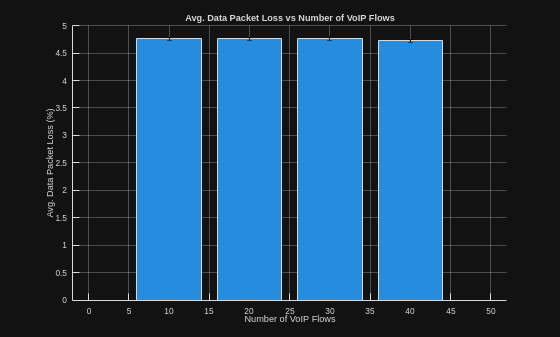

% ex2.b

figure(1);
hold on;
grid on;
bar(n, PLd_values');                                        % Bar Graph
er = errorbar(n, PLd_values', PLd_terms);                   % Set the error bar
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Data Packet Loss (%)')
title('Avg. Data Packet Loss vs Number of VoIP Flows');
hold off;

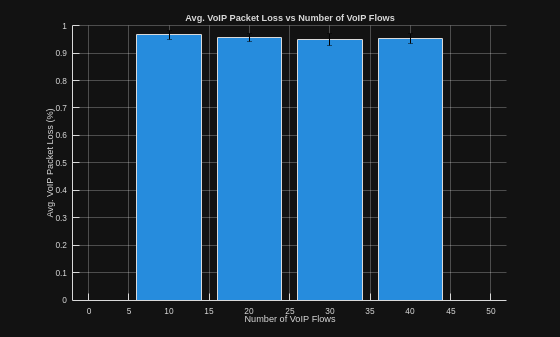


figure(2);
hold on;
grid on;
bar(n, PLv_values');                                   % Bar Graph
er = errorbar(n, PLv_values', PLv_terms);              % Set the error bar
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. VoIP Packet Loss (%)')
title('Avg. VoIP Packet Loss vs Number of VoIP Flows');
hold off;

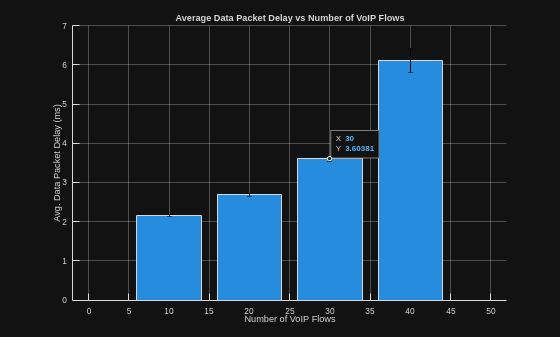

% ex2.c

figure(3);
hold on;
grid on;
bar(n, APDd_values');                                  % Bar Graph
ylim([0 7]);                                                % Set y axis values between 0 and 7
er = errorbar(n, APDd_values', APDd_terms);            % Set the error bar
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Data Packet Delay (ms)')
title('Average Data Packet Delay vs Number of VoIP Flows');
hold off;

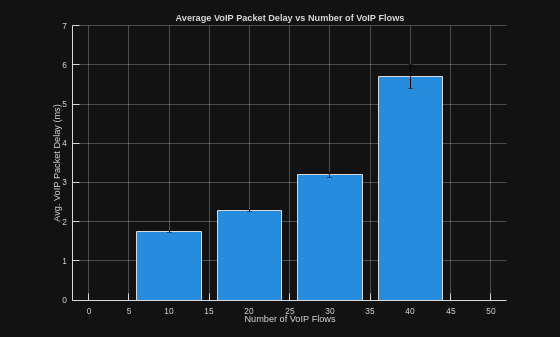


figure(4);
hold on;
grid on;
bar(n, APDv_values');                                  % Bar Graph
ylim([0 7]);                                                % Set y axis values between 0 and 7
er = errorbar(n, APDv_values', APDv_terms);            % Set the error bar
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. VoIP Packet Delay (ms)')
title('Average VoIP Packet Delay vs Number of VoIP Flows');
hold off;

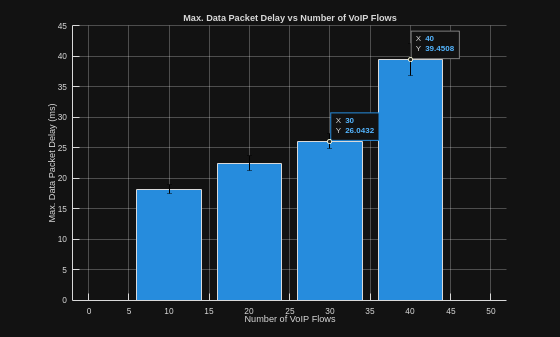

% ex2.d

figure(5);
hold on;
grid on;
bar(n, MPDd_values');                                        % Bar Graph for Data Max Delay
er = errorbar(n, MPDd_values', MPDd_terms);                  % Set the error bar
er.Color = [0 0 0];                                          % Error bar color
er.LineStyle = 'none';                                       % No line for error bar
xlabel('Number of VoIP Flows')
ylabel('Max. Data Packet Delay (ms)')
title('Max. Data Packet Delay vs Number of VoIP Flows');
hold off;

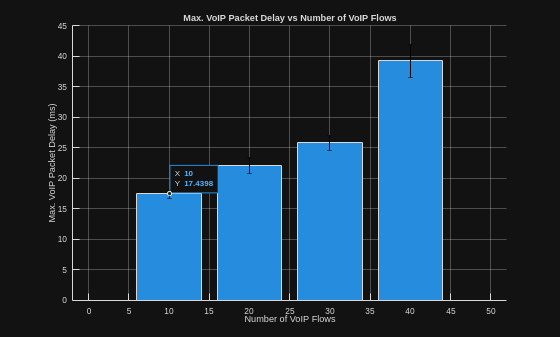


figure(6);
hold on;
grid on;
bar(n, MPDv_values');                                        % Bar Graph for VoIP Max Delay
er = errorbar(n, MPDv_values', MPDv_terms);                  % Set the error bar
er.Color = [0 0 0];                                          % Error bar color
er.LineStyle = 'none';                                       % No line for error bar
xlabel('Number of VoIP Flows')
ylabel('Max. VoIP Packet Delay (ms)')
title('Max. VoIP Packet Delay vs Number of VoIP Flows');
hold off;

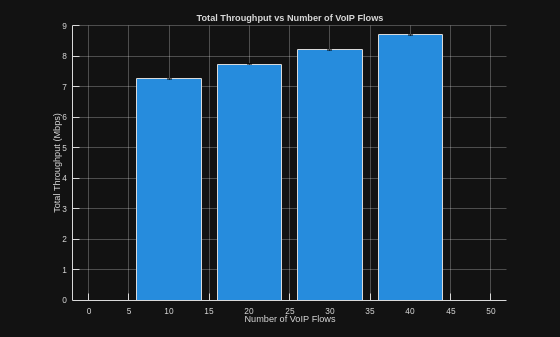

% ex2.e

figure(7);
hold on;
grid on;
bar(n, TT_values');                                          % Bar Graph for Total Throughput
er = errorbar(n, TT_values', TT_terms);                      % Set the error bar
er.Color = [0 0 0];                                          % Error bar color
er.LineStyle = 'none';                                       % No line for error bar
xlabel('Number of VoIP Flows')
ylabel('Total Throughput (Mbps)')
title('Total Throughput vs Number of VoIP Flows');
hold off;

#### 2.f)Determine the theoretical value of the total throughput for all cases simulated in experiment 2.a. Present and explain the MATLAB code developed for these calculations. Compare these values with the results obtained in 2.e. What do you conclude?

P = 100000;
L = 1500;
Lv = (1/20e-3); % uniform distribution around the average inter arrival time of 20 milliseconds
C = 10*10^6;
F = 1000000;
B = 10^-5;
n = [10 20 30 40];

elements = (109-65+1)+(1517-111+1);

probleft = 100 - (19 + 23 + 17);
probelem = (probleft / elements)/100;

prob_voip = 1 / (130 - 110 + 1);

avgpacketdata = 0.19 * 64 + 0.23*110 + 0.17 * 1518 + sum((65:109)*(probelem))+sum((111:1517)*(probelem));

avgpacketvoip = sum((110:130)*prob_voip); 

TT = zeros(1,length(n));

for i = 1:length(n)
    
    fprintf('For n = %d VoIP flows \n', n(i));

    throughput = ((L * avgpacketdata) + ((Lv * n(i)) * avgpacketvoip))* 8 /10^6;
    TT(i) = throughput;

    fprintf('Throughput (Mbps)         = %0.4f\n',TT(i));

end
